%Variables

%Zero-lift drag coefficient
Cd0 = 0.025;
%Wing area (m^2)
S = 16.17;
%Aspect ratio
Ar = 7.32;
%Number of simultaneous equations
n = 10;
%Values of theta
theta = linspace(10*pi()/180, 80*pi()/180, n);
%Wing span(m)
b = 11;
%Lift curve slope (1/rad)
a0 = 2*pi();
%Root chord (m)
c_root = 1.63;
%Tip chord (m)
c_tip = 1.13;
%Span location where tapering begins (m)
taper_loc = 2.68;
%Aircraft mass (kg)
mass = 1157;
%Acceleration due to gravity (m/s^2)
g = 9.81;
%Air density (kg/m^3)
rho = 1.225;
%Time steps (s)
dt = [1, 0.5, 0.2, 0.1, 0.05, 0.02, 0.01, 0.005, 0.002, 0.001, 0.0005, 0.0002, 0.0001];
%Maximum lift coefficient of airfoil
CLmax = 1.54;
%Stall velocity (m/s)
V_s = sqrt((2*mass*g)/(rho*CLmax*S));
%Propeller efficiency
eta = 0.8;
%Engine power (W)
P = 134226;
%Propeller radius (m)
Rp = 0.965;
%Propeller disk area (m^2)
Ap = pi*Rp^2;
%Empty velocity and distance vectors
V = [0,0];
S_t = [0,0];
%Matrices to input calculated values into
B = zeros(n, 1);
X = zeros(n, n);
nu = zeros(n, 1);
c = zeros(n, 1);

%Lifting line theory
for i = 1:n
    L = 0.5 * b * cos(theta(i));
    if L > taper_loc
        c(i) = (c_root - c_tip)*(0.5*b*(1-cos(theta(i))))/(0.5*b - taper_loc) + c_tip;
    else
        c(i) = c_root;
    end
    nu(i) = (c(i)*a0)/(4*b) ;
    alpha_0 = -pi()/180;
    B(i) = nu(i) * sin(theta(1, i)) * -(alpha_0);
    for j = 1:n
        X(i, j) = sin((2*j - 1)*theta(1, i))*(sin(theta(1, i)) + (2*j - 1)*nu(i));
    end
end

solutions = X\B;
C_l = solutions(1)*pi()*Ar;

delta = 0;
for i = 2:n
    delta = delta + (2*i - 1)*(solutions(i)/solutions(1))^2;
end

e = 1/(1 + delta);
C_d = Cd0 + (C_l^2/(pi()*e*Ar));

K1 = (2*eta*P)/(rho*Ap);
error_quadratic = zeros(13, 16600);
error_euler = zeros(13, 16600);
exact = [22.681445265, 23.966766831, 25.2951345316, 26.6672529823, 28.0838437972, 29.5456478192, 31.0534274028, 32.6079577952, 34.2100386033, 35.8604896023, 37.5601510079, 39.3098918068, 41.1105960683, 42.9631752713, 44.8685640021, 46.8277323958, 48.8416708693, 50.9114011276, 53.037971584, 55.2224679394, 57.4660030292, 59.7697312721, 62.1348320783, 64.5625290542, 67.0540945016, 69.6108177434, 72.2340553155, 74.9251969697, 77.685678994, 80.5169907576, 83.4206731839, 86.398319936, 89.4515792158, 92.5821776053, 95.7918663759, 99.0825067543, 102.456003128, 105.914340456, 109.459591453, 113.093891972, 116.819472671, 120.638666499, 124.553894659, 128.567696589, 132.682670433, 136.901597138, 141.22734011, 145.662905253, 150.211435204, 154.876215607, 159.660714565, 164.568516569, 169.603444407, 174.769490342, 180.070841196, 185.511904653, 191.097362344, 196.832107335, 202.721326666, 208.770511139, 214.985459078, 221.372320337, 227.937619737, 234.688284728, 241.631713194, 248.775741498, 256.128759613, 263.699739491, 271.498263953, 279.534638598, 287.819895549, 296.36594712, 305.185605674, 314.292756299, 323.702421742, 333.43087468, 343.495908461, 353.916856967, 364.714946072, 375.913443991, 387.537967303, 399.616820281, 412.181423572, 425.266718181, 438.911808644, 453.160572792, 468.062573815, 483.674036486, 500.059150577, 517.291669728, 535.456892114, 554.654290935, 575.00087826, 596.635583489, 619.725258025, 644.472642777, 671.12776118, 700.003839418, 731.500963188, 766.141678546];

tic
for w = 1:166
    P = 125000 + 451.8*w;
    for k = 1:100
        mass = 390 + 10*k;
        K4 = -(rho*S/(2*mass))*(Cd0 + (C_l^2)/(pi*e*Ar));
        for j = 1:13
            V_s = sqrt((2*mass*g)/(rho*CLmax*S));
            a = [0];
            V = [0];
            S_t = [0];
            i = 1;
            while V(i) < 1.2*V_s
                K2 = -V(i)/3;
                Ve = (K2^3 + K1 + sqrt(2*K2^3 * K1 + K1^2))^(1/3) + (K2^3 + K1 - sqrt(2*K2^3 * K1 + K1^2))^(1/3) + K2;
                T = 0.5 * rho * Ap * (Ve + 3*K2) * (Ve - 3*K2);
                K3 = T/mass;
                i = i + 1;
                V(i) = 1/(K4*dt(j)) + sqrt(1/(K4^2 * dt(j)^2) - V(i - 1)^2 - (2*K3)/K4 - (2*V(i - 1))/(K4*dt(j)));
                S_t(i) = S_t(i - 1) + (V(i) + V(i - 1))*dt(j)/2;
            end
            S_t(i) = (1.2*V_s - V(i - 1))*(S_t(i) - S_t(i - 1))/(V(i) - V(i - 1)) + S_t(i - 1);
        
            dt(j);
            S_takeoff = max(real(S_t));
            error_quadratic(j, 100*(w-1)+k) = abs((exact(k) - S_takeoff)*100/(exact(k)));
        
            %Empty acceleration, velocity and distance vectors
            a = [0];
            V = [0];
            S_t = [0];
        
            i = 1;
            while V(i) < 1.2*V_s
                K2 = -V(i)/3;
                Ve = (K2^3 + K1 + sqrt(2*K2^3 * K1 + K1^2))^(1/3) + (K2^3 + K1 - sqrt(2*K2^3 * K1 + K1^2))^(1/3) + K2;
                T = 0.5 * rho * Ap * (Ve + 3*K2) * (Ve - 3*K2);
                K3 = T/mass;
                i = i + 1;
                a(i) = K3 + K4*V(i - 1)^2;
                V(i) = V(i - 1) + a(i - 1)*dt(j);
                S_t(i) = S_t(i - 1) + V(i - 1)*dt(j);
            end
            S_t(i) = (1.2*V_s - V(i - 1))*(S_t(i) - S_t(i - 1))/(V(i) - V(i - 1)) + S_t(i - 1);
        
            S_takeoff = max(real(S_t));
            error_euler(j, 100*(w-1)+k) = abs((exact(k) - S_takeoff)*100/(exact(k)));
        end
    end
    w
end

w = 1

w = 2

w = 3

w = 4

w = 5

w = 6

w = 7

w = 8

w = 9

w = 10

w = 11

w = 12

w = 13

w = 14

w = 15

w = 16

w = 17

w = 18

w = 19

w = 20

w = 21

w = 22

w = 23

w = 24

w = 25

w = 26

w = 27

w = 28

w = 29

w = 30

w = 31

w = 32

w = 33

w = 34

w = 35

w = 36

w = 37

w = 38

w = 39

w = 40

w = 41

w = 42

w = 43

w = 44

w = 45

w = 46

w = 47

w = 48

w = 49

w = 50

w = 51

w = 52

w = 53

w = 54

w = 55

w = 56

w = 57

w = 58

w = 59

w = 60

w = 61

w = 62

w = 63

w = 64

w = 65

w = 66

w = 67

w = 68

w = 69

w = 70

w = 71

w = 72

w = 73

w = 74

w = 75

w = 76

w = 77

w = 78

w = 79

w = 80

w = 81

w = 82

w = 83

w = 84

w = 85

w = 86

w = 87

w = 88

w = 89

w = 90

w = 91

w = 92

w = 93

w = 94

w = 95

w = 96

w = 97

w = 98

w = 99

w = 100

w = 101

w = 102

w = 103

w = 104

w = 105

w = 106

w = 107

w = 108

w = 109

w = 110

w = 111

w = 112

w = 113

w = 114

w = 115

w = 116

w = 117

w = 118

w = 119

w = 120

w = 121

w = 122

w = 123

w = 124

w = 125

w = 126

w = 127

w = 128

w = 129

w = 130

w = 131

w = 132

w = 133

w = 134

w = 135

w = 136

w = 137

w = 138

w = 139

w = 140

w = 141

w = 142

w = 143

w = 144

w = 145

w = 146

w = 147

w = 148

w = 149

w = 150

w = 151

w = 152

w = 153

w = 154

w = 155

w = 156

w = 157

w = 158

w = 159

w = 160

w = 161

w = 162

w = 163

w = 164

w = 165

w = 166

toc

Elapsed time is 6187.037199 seconds.


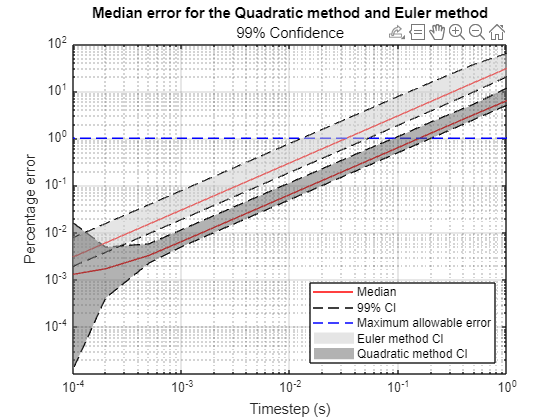


median_quadratic = [0, 0];
median_euler = [0, 0];
LB_euler = [0, 0];
UB_euler = [0, 0];
LB_quadratic = [0, 0];
UB_quadratic = [0, 0];

critical_error = ones(1, 13);


for i = 1:13
    median_quadratic(i) = median(error_quadratic(i,:));
end

sorted_quadratic = sort(error_quadratic, 2);

for i = 1:13
    LB_quadratic(i) = sorted_quadratic(i,166);
    UB_quadratic(i) = sorted_quadratic(i,16434);
end

for i = 1:13
    median_euler(i) = median(error_euler(i,:));
end

sorted_euler = sort(error_euler, 2);

for i = 1:13
    LB_euler(i) = sorted_euler(i,166);
    UB_euler(i) = sorted_euler(i,16434);
end


loglog(dt, median_quadratic, "r")
hold on
loglog(dt, LB_quadratic, "k--")
hold on
loglog(dt, UB_quadratic, "k--")
title("Median error for the Quadratic method and Euler method")
subtitle("99% Confidence")
xlim([0.0001, 1])
ylim([0.00001, 100])
xlabel("Timestep (s)")
ylabel("Percentage error")
loglog(dt, median_euler, "r")
hold on
loglog(dt, LB_euler, "k--")
hold on
loglog(dt, UB_euler, "k--")
hold on
loglog(dt, critical_error, "b--")
patch([dt fliplr(dt)], [LB_euler fliplr(UB_euler)], [.8, .8, .8], 'FaceAlpha',0.5, 'EdgeColor','none')
patch([dt fliplr(dt)], [LB_quadratic fliplr(UB_quadratic)], [.4, .4, .4], 'FaceAlpha',0.5, 'EdgeColor','none')
legend("Median", "99% CI", '', '', '', '', "Maximum allowable error", "Euler method CI", "Quadratic method CI", Location="southeast")
grid on
hold off


    %Variables
    
    %Zero-lift drag coefficient
    Cd0 = 0.025;
    %Wing area (m^2)
    S = 16.17;
    %Aspect ratio
    Ar = 7.32;
    %Number of simultaneous equations
    n = 10;
    %Values of theta
    theta = linspace(10*pi()/180, 80*pi()/180, n);
    %Wing span(m)
    b = 11;
    %Lift curve slope (1/rad)
    a0 = 2*pi();
    %Root chord (m)
    c_root = 1.63;
    %Tip chord (m)
    c_tip = 1.13;
    %Span location where tapering begins (m)
    taper_loc = 2.68;
    %Aircraft mass (kg)
    mass = 800;
    %Acceleration due to gravity (m/s^2)
    g = 9.81;
    %Air density (kg/m^3)
    rho = 1.225;
    %Time steps (s)
    dt = 0.11;
    %Maximum lift coefficient of airfoil
    CLmax = 1.54;
    %Stall velocity (m/s)
    V_s = sqrt((2*mass*g)/(rho*CLmax*S));
    %Propeller efficiency
    eta = 0.8;
    %Engine power (W)
    P = 134226;
    %Propeller radius (m)
    Rp = 0.965;
    %Propeller disk area (m^2)
    Ap = pi*Rp^2;
    %Empty velocity and distance vectors
    V = [0,0];
    S_t = [0,0];
    %Matrices to input calculated values into
    B = zeros(n, 1);
    X = zeros(n, n);
    nu = zeros(n, 1);
    c = zeros(n, 1);

    %Lifting line theory
    for i = 1:n
        L = 0.5 * b * cos(theta(i));
        if L > taper_loc
            c(i) = (c_root - c_tip)*(0.5*b*(1-cos(theta(i))))/(0.5*b - taper_loc) + c_tip;
        else
            c(i) = c_root;
        end
        nu(i) = (c(i)*a0)/(4*b) ;
        alpha_0 = -pi()/180;
        B(i) = nu(i) * sin(theta(1, i)) * -(alpha_0);
        for j = 1:n
            X(i, j) = sin((2*j - 1)*theta(1, i))*(sin(theta(1, i)) + (2*j - 1)*nu(i));
        end
    end
    
    solutions = X\B;
    C_l = solutions(1)*pi()*Ar;
    
    delta = 0;
    for i = 2:n
        delta = delta + (2*i - 1)*(solutions(i)/solutions(1))^2;
    end
    
    e = 1/(1 + delta);
    C_d = Cd0 + (C_l^2/(pi()*e*Ar));
    
    V_s = sqrt((2*mass*g)/(rho*CLmax*S));
    a = [0];
    V = [0];
    S_t = [0];
    i = 1;
    K1 = (2*eta*P)/(rho*Ap);
    K4 = -(rho*S/(2*mass))*(Cd0 + (C_l^2)/(pi*e*Ar));
    tic
for j = 1:10000000
    while V(i) < 1.2*V_s
        K2 = -V(i)/3;
        Ve = (K2^3 + K1 + sqrt(2*K2^3 * K1 + K1^2))^(1/3) + (K2^3 + K1 - sqrt(2*K2^3 * K1 + K1^2))^(1/3) + K2;
        T = 0.5 * rho * Ap * (Ve + 3*K2) * (Ve - 3*K2);
        K3 = T/mass;
        i = i + 1;
        V(i) = 1/(K4*dt) + sqrt(1/(K4^2 * dt^2) - V(i - 1)^2 - (2*K3)/K4 - (2*V(i - 1))/(K4*dt));
        S_t(i) = S_t(i - 1) + (V(i) + V(i - 1))*dt/2;
    end
    S_t(i) = (1.2*V_s - V(i - 1))*(S_t(i) - S_t(i - 1))/(V(i) - V(i - 1)) + S_t(i - 1);
end
    toc

Elapsed time is 0.090178 seconds.


    S_takeoff = max(real(S_t));


    %Variables
    
    %Zero-lift drag coefficient
    Cd0 = 0.025;
    %Wing area (m^2)
    S = 16.17;
    %Aspect ratio
    Ar = 7.32;
    %Number of simultaneous equations
    n = 10;
    %Values of theta
    theta = linspace(10*pi()/180, 80*pi()/180, n);
    %Wing span(m)
    b = 11;
    %Lift curve slope (1/rad)
    a0 = 2*pi();
    %Root chord (m)
    c_root = 1.63;
    %Tip chord (m)
    c_tip = 1.13;
    %Span location where tapering begins (m)
    taper_loc = 2.68;
    %Aircraft mass (kg)
    mass = 800;
    %Acceleration due to gravity (m/s^2)
    g = 9.81;
    %Air density (kg/m^3)
    rho = 1.225;
    %Time steps (s)
    dt = 0.015;
    %Maximum lift coefficient of airfoil
    CLmax = 1.54;
    %Stall velocity (m/s)
    V_s = sqrt((2*mass*g)/(rho*CLmax*S));
    %Propeller efficiency
    eta = 0.8;
    %Engine power (W)
    P = 134226;
    %Propeller radius (m)
    Rp = 0.965;
    %Propeller disk area (m^2)
    Ap = pi*Rp^2;
    %Empty velocity and distance vectors
    V = [0,0];
    S_t = [0,0];
    %Matrices to input calculated values into
    B = zeros(n, 1);
    X = zeros(n, n);
    nu = zeros(n, 1);
    c = zeros(n, 1);

    %Lifting line theory
    for i = 1:n
        L = 0.5 * b * cos(theta(i));
        if L > taper_loc
            c(i) = (c_root - c_tip)*(0.5*b*(1-cos(theta(i))))/(0.5*b - taper_loc) + c_tip;
        else
            c(i) = c_root;
        end
        nu(i) = (c(i)*a0)/(4*b) ;
        alpha_0 = -pi()/180;
        B(i) = nu(i) * sin(theta(1, i)) * -(alpha_0);
        for j = 1:n
            X(i, j) = sin((2*j - 1)*theta(1, i))*(sin(theta(1, i)) + (2*j - 1)*nu(i));
        end
    end
    
    solutions = X\B;
    C_l = solutions(1)*pi()*Ar;
    
    delta = 0;
    for i = 2:n
        delta = delta + (2*i - 1)*(solutions(i)/solutions(1))^2;
    end
    
    e = 1/(1 + delta);
    C_d = Cd0 + (C_l^2/(pi()*e*Ar));
    
    V_s = sqrt((2*mass*g)/(rho*CLmax*S));
    a = [0];
    V = [0];
    S_t = [0];
    i = 1;
    K1 = (2*eta*P)/(rho*Ap);
    K4 = -(rho*S/(2*mass))*(Cd0 + (C_l^2)/(pi*e*Ar));
    tic
for j = 1:10000000
    while V(i) < 1.2*V_s
        K2 = -V(i)/3;
        Ve = (K2^3 + K1 + sqrt(2*K2^3 * K1 + K1^2))^(1/3) + (K2^3 + K1 - sqrt(2*K2^3 * K1 + K1^2))^(1/3) + K2;
        T = 0.5 * rho * Ap * (Ve + 3*K2) * (Ve - 3*K2);
        K3 = T/mass;
        i = i + 1;
        a(i) = K3 + K4*V(i - 1)^2;
        V(i) = V(i - 1) + a(i - 1)*dt;
        S_t(i) = S_t(i - 1) + V(i - 1)*dt;
    end
    S_t(i) = (1.2*V_s - V(i - 1))*(S_t(i) - S_t(i - 1))/(V(i) - V(i - 1)) + S_t(i - 1);
end
    toc

Elapsed time is 0.090020 seconds.


    S_takeoff = max(real(S_t));